clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater_newmonkey';
cd(workingpath);

files=dir('*top.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-8),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201001_top.csv


   56.2673  125.4151  194.5630   64.4272   98.1361  131.8450



吲哚_R_20200930_top.csv


   54.2995  122.3422  190.3850   67.1329  102.1270  137.1210



异戊酸_L_20200929_top.csv


   53.1225  121.6917  190.2610   66.0996   99.3773  132.6550



异戊酸_R_20200926_top.csv


   95.9620  148.8110  201.6600   79.4112  108.2996  137.1880



白桃_L_20201003_top.csv


   55.9635  124.9228  193.8820   56.6824   95.3447  134.0070



白桃_R_20201004_top.csv


   56.4970  125.4910  194.4850   55.4538   92.7459  130.0380



香蕉_L_20201008_top.csv


   66.3677  128.3604  190.3530   60.8057   95.2284  129.6510



香蕉_R_20201009_top.csv


   56.7712  139.0971  221.4230   51.9538   95.0794  138.2050



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 2.4300e+04
          df: 1
       edges: [0 100 200]
           O: [69045 22007]
           E: [45526 45526]


    90   110



pvalue = 0

st =     chi2stat: 2.6821e+04
          df: 1
       edges: [0 100 200]
           O: [67539 19283]
           E: [43411 43411]


    80   120



pvalue = 0

st =     chi2stat: 2.8201e+04
          df: 1
       edges: [0 100 200]
           O: [66179 17578]
           E: [4.1878e+04 4.1878e+04]


吲哚-R-20200930


   100   100



pvalue = 0

st =     chi2stat: 9.2685e+03
          df: 1
       edges: [0 100 200]
           O: [60440 31283]
           E: [4.5862e+04 4.5862e+04]


    90   110



pvalue = 0

st =     chi2stat: 9.4008e+03
          df: 1
       edges: [0 100 200]
           O: [55282 27402]
           E: [41342 41342]


    80   120



pvalue = 0

st =     chi2stat: 8.9671e+03
          df: 1
       edges: [0 100 200]
           O: [50503 24559]
           E: [37531 37531]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 2.2411e+04
          df: 1
       edges: [0 100 200]
           O: [67536 22593]
           E: [4.5064e+04 4.5064e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.2715e+04
          df: 1
       edges: [0 100 200]
           O: [64180 20359]
           E: [4.2270e+04 4.2270e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.1880e+04
          df: 1
       edges: [0 100 200]
           O: [59330 18155]
           E: [3.8742e+04 3.8742e+04]


异戊酸-R-20200926


   100   100



pvalue = 0

st =     chi2stat: 8.0411e+03
          df: 1
       edges: [0 100 200]
           O: [63352 35201]
           E: [4.9276e+04 4.9276e+04]


    90   110



pvalue = 0

st =     chi2stat: 7.5419e+03
          df: 1
       edges: [0 100 200]
           O: [61033 34229]
           E: [47631 47631]


    80   120



pvalue = 0

st =     chi2stat: 7.5911e+03
          df: 1
       edges: [0 100 200]
           O: [56677 30894]
           E: [4.3786e+04 4.3786e+04]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 1.0551e+04
          df: 1
       edges: [0 100 200]
           O: [61755 30548]
           E: [4.6152e+04 4.6152e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.3551e+04
          df: 1
       edges: [0 100 200]
           O: [60145 25982]
           E: [4.3064e+04 4.3064e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.5703e+04
          df: 1
       edges: [0 100 200]
           O: [58676 22888]
           E: [40782 40782]


白桃-R-20201004


   100   100



pvalue = 0

st =     chi2stat: 1.5235e+04
          df: 1
       edges: [0 100 200]
           O: [69967 30788]
           E: [5.0378e+04 5.0378e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7402e+04
          df: 1
       edges: [0 100 200]
           O: [66798 26504]
           E: [46651 46651]


    80   120



pvalue = 0

st =     chi2stat: 1.9189e+04
          df: 1
       edges: [0 100 200]
           O: [64957 23709]
           E: [44333 44333]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 2.1324e+04
          df: 1
       edges: [0 100 200]
           O: [68432 24029]
           E: [4.6230e+04 4.6230e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.3610e+04
          df: 1
       edges: [0 100 200]
           O: [65810 20633]
           E: [4.3222e+04 4.3222e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.4477e+04
          df: 1
       edges: [0 100 200]
           O: [63603 18715]
           E: [41159 41159]


香蕉-R-20201009


   100   100



pvalue = 9.0705e-58

st =     chi2stat: 256.6827
          df: 1
       edges: [0 100 200]
           O: [47511 42699]
           E: [45105 45105]


    90   110



pvalue = 4.4497e-43

st =     chi2stat: 189.3312
          df: 1
       edges: [0 100 200]
           O: [45167 41125]
           E: [43146 43146]


    80   120



pvalue = 1.5867e-19

st =     chi2stat: 81.6965
          df: 1
       edges: [0 100 200]
           O: [42157 39573]
           E: [40865 40865]


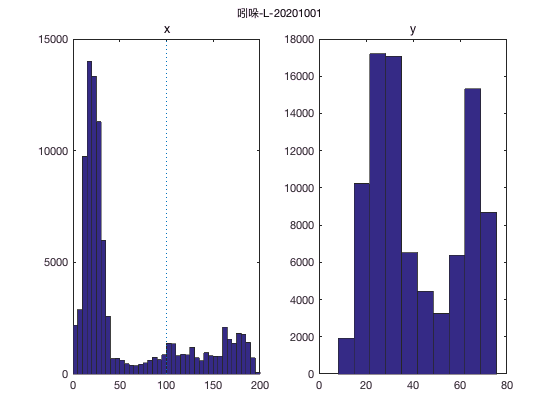

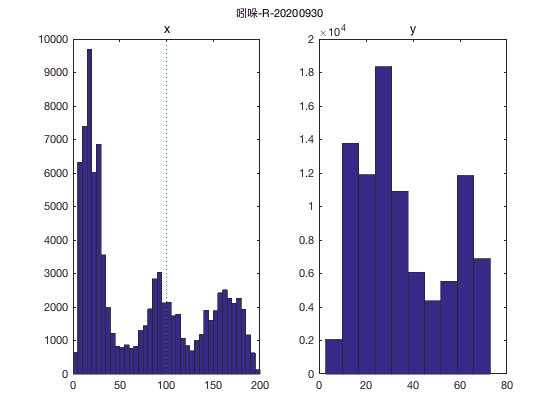

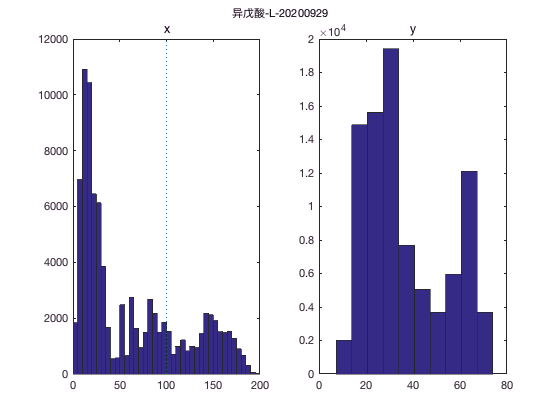

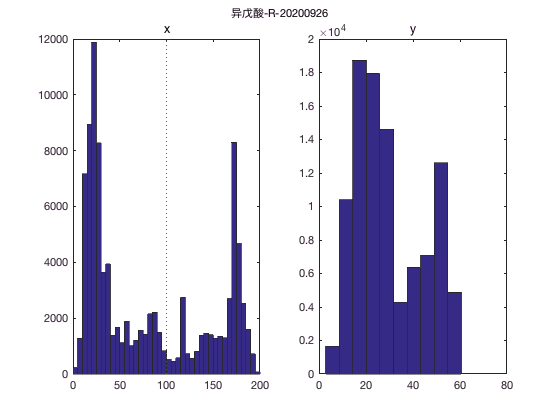

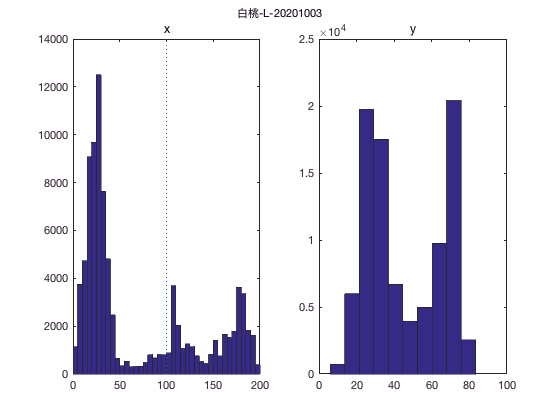

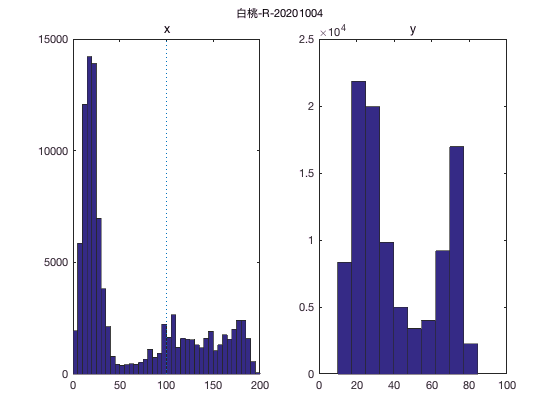

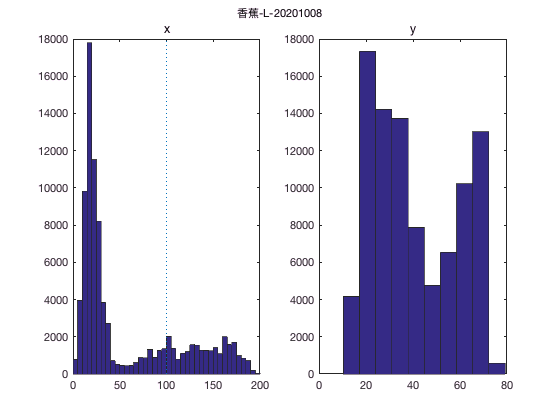

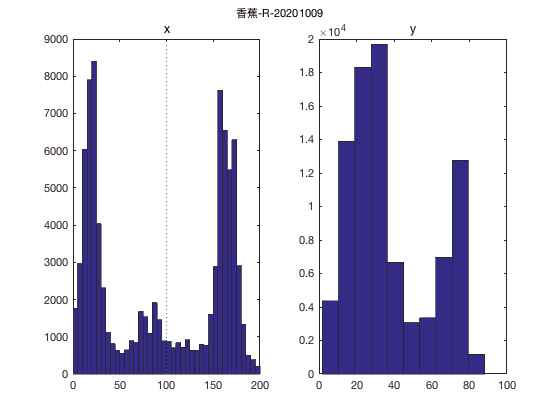

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 9.6766e+04
          df: 1
       edges: [0 100 200]
           O: [508038 239148]
           E: [373593 373593]


    90   110



pvalue = 0

st =     chi2stat: 1.0426e+05
          df: 1
       edges: [0 100 200]
           O: [485954 215517]
           E: [3.5074e+05 3.5074e+05]


    80   120



pvalue = 0

st =     chi2stat: 1.0752e+05
          df: 1
       edges: [0 100 200]
           O: [462082 196071]
           E: [3.2908e+05 3.2908e+05]


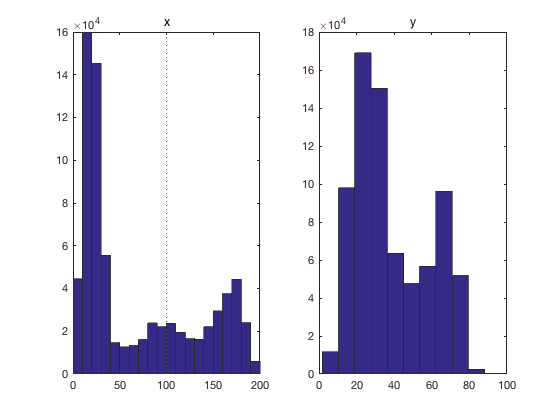


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

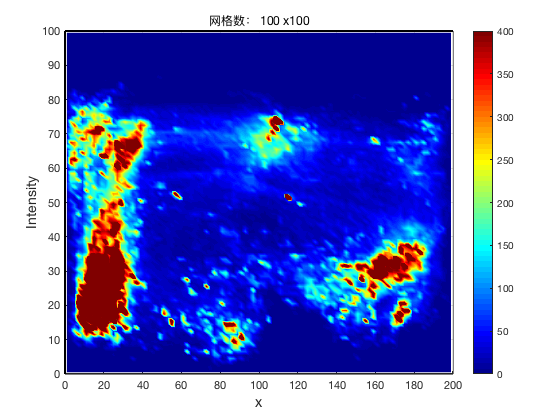

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 36.349395 秒。


## 合并odor两个条件

吲哚-L-20201001


   100   100



pvalue = 0

st =     chi2stat: 1.4417e+04
          df: 1
       edges: [0 100 200]
           O: [100328 82447]
           E: [1.2428e+05 5.8500e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.4016e+04
          df: 1
       edges: [0 100 200]
           O: [94941 74565]
           E: [1.1743e+05 5.2078e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.2983e+04
          df: 1
       edges: [0 100 200]
           O: [90738 68081]
           E: [1.1151e+05 4.7314e+04]


异戊酸-L-20200929


   100   100



pvalue = 0

st =     chi2stat: 1.5904e+04
          df: 1
       edges: [0 100 200]
           O: [102737 85945]
           E: [1.2829e+05 6.0390e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7870e+04
          df: 1
       edges: [0 100 200]
           O: [98409 81392]
           E: [1.2456e+05 5.5241e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.9072e+04
          df: 1
       edges: [0 100 200]
           O: [90224 74832]
           E: [1.1588e+05 4.9172e+04]


白桃-L-20201003


   100   100



pvalue = 0

st =     chi2stat: 3.5692e+04
          df: 1
       edges: [0 100 200]
           O: [92543 100515]
           E: [1.3127e+05 6.1791e+04]


    90   110



pvalue = 0

st =     chi2stat: 3.7124e+04
          df: 1
       edges: [0 100 200]
           O: [86649 92780]
           E: [1.2430e+05 5.5127e+04]


    80   120



pvalue = 0

st =     chi2stat: 3.8723e+04
          df: 1
       edges: [0 100 200]
           O: [82385 87845]
           E: [1.1952e+05 5.0713e+04]


香蕉-L-20201008


   100   100



pvalue = 0

st =     chi2stat: 4.2994e+03
          df: 1
       edges: [0 100 200]
           O: [111131 71540]
           E: [1.2420e+05 5.8467e+04]


    90   110



pvalue = 0

st =     chi2stat: 4.4075e+03
          df: 1
       edges: [0 100 200]
           O: [106935 65800]
           E: [1.1966e+05 5.3070e+04]


    80   120



pvalue = 0

st =     chi2stat: 4.1970e+03
          df: 1
       edges: [0 100 200]
           O: [103176 60872]
           E: [1.1518e+05 4.8872e+04]


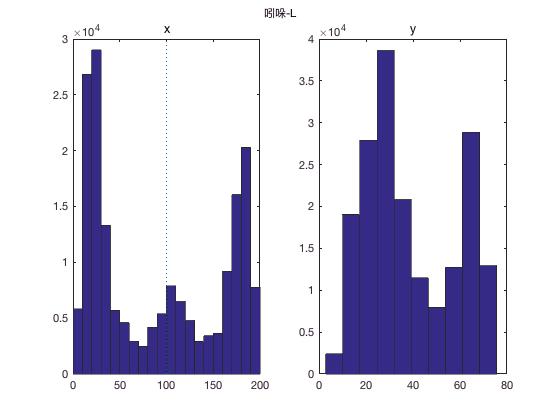

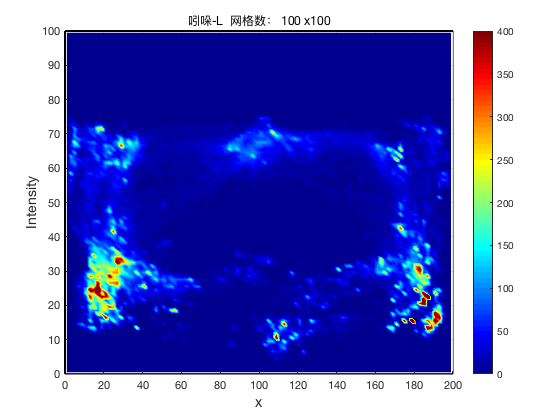

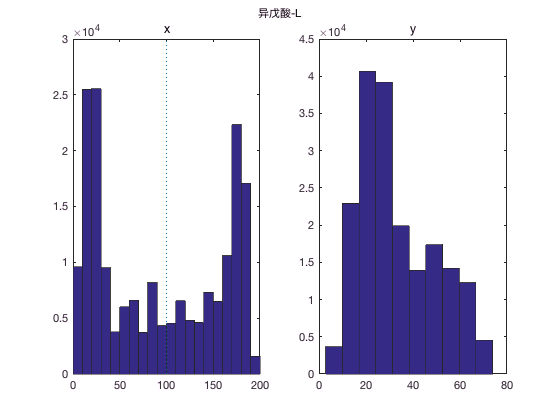

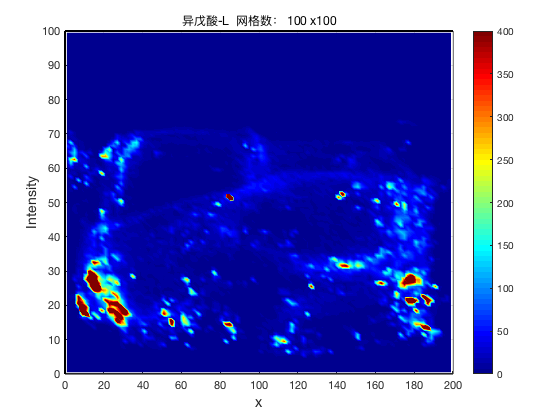

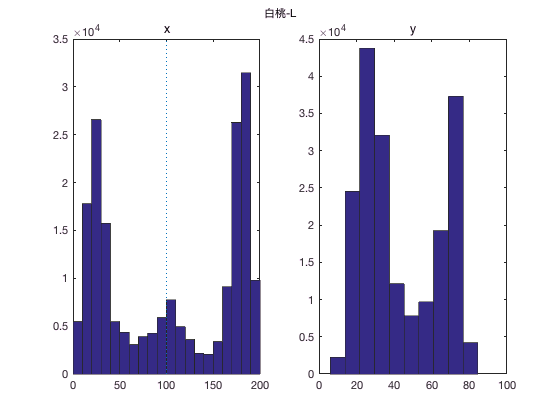

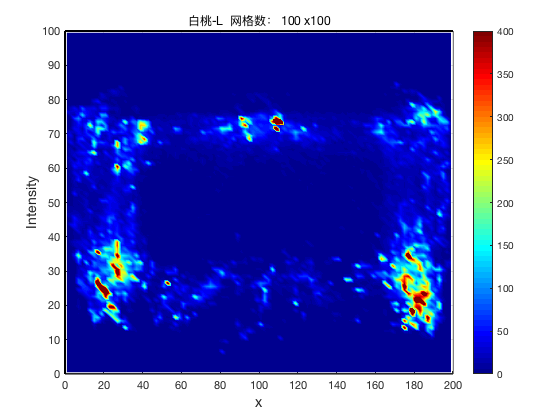

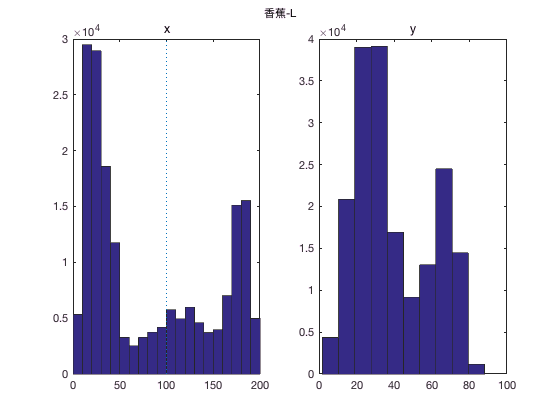

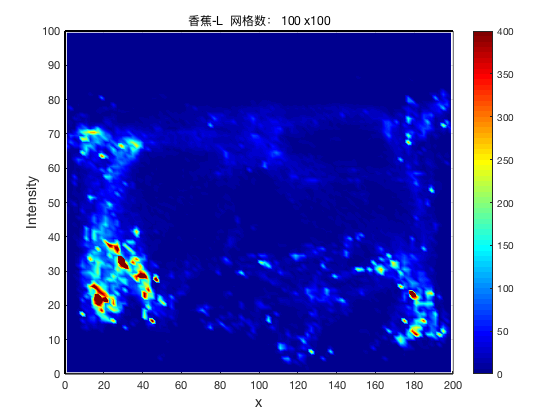

tic;
interval=10;
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1};data];

    % chisq test
    disp(conditions{odor-1})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 49.520002 秒。


## 合并odor两个条件的（只取前面一段时间）

   100   100



pvalue = 0

st =     chi2stat: 2.0486e+03
          df: 1
       edges: [0 100 200]
           O: [13861 7280]
           E: [1.0570e+04 1.0570e+04]


   100   100



pvalue = 7.1215e-112

st =     chi2stat: 505.1724
          df: 1
       edges: [0 100 200]
           O: [9962 7032]
           E: [8497 8497]


   100   100



pvalue = 7.8686e-69

st =     chi2stat: 307.4447
          df: 1
       edges: [0 100 200]
           O: [10112 12764]
           E: [11438 11438]


   100   100



pvalue = 0

st =     chi2stat: 5.3879e+03
          df: 1
       edges: [0 100 200]
           O: [14894 4636]
           E: [9765 9765]


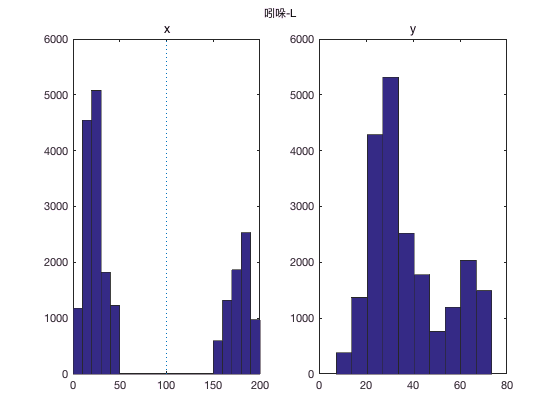

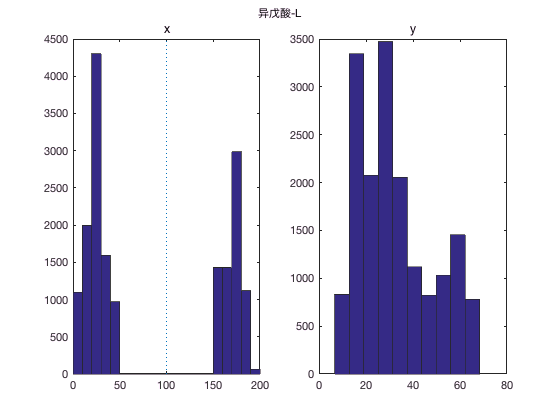

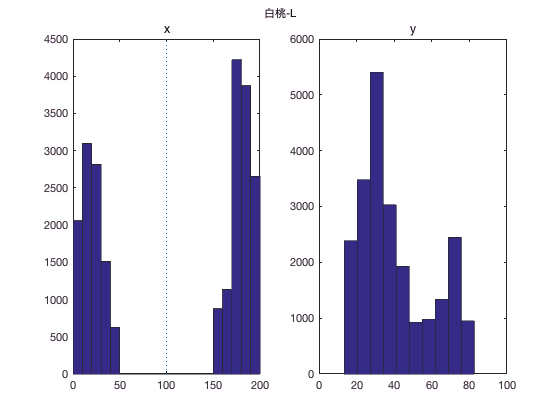

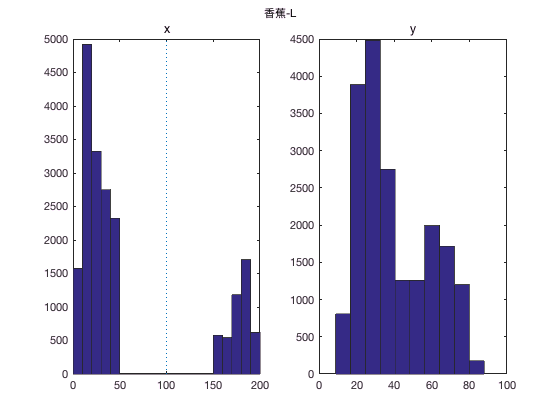

interval=10;
timeint=10;%minute
p1=1;
p2=timeint*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-20201001


-------------


100-100


        9534        4116
       10483        3167
       10264        3386
       10462        3188
       10507        3143
       11145        2505
        6650        2502



  593.6181



  5.5504e-125



-------------


-------------


90-110


        9280        4370
       10310        3340
        9979        3671
       10162        3488
       10294        3356
       10973        2677
        6541        2611



  615.7630



  9.2752e-130



-------------


-------------


80-120


        9009        4641
       10167        3483
        9847        3803
        9772        3878
       10089        3561
       10821        2829
        6474        2678



  666.1149



  1.2636e-140



-------------


-------------


70-130


        8838        4812
       10028        3622
        9736        3914
        9547        4103
        9986        3664
       10696        2954
        6412        2740



  691.8327



  3.5470e-146



-------------


-------------


60-140


        8685        4965
        9924        3726
        9597        4053
        9456        4194
        9866        3784
       10593        3057
        6361        2791



  708.4771



  9.0398e-150



-------------


-------------


50-150


        8442        5208
        9815        3835
        9238        4412
        9344        4306
        9760        3890
       10490        3160
        6307        2845



  819.2666



  1.0578e-173



-------------


吲哚-R-20200930


-------------


100-100


        6972        6678
        8265        5385
        8686        4964
       10848        2802
        7868        5782
       10315        3335
        7486        2337



   4.1050e+03



     0



-------------


-------------


90-110


        6204        7446
        6858        6792
        8311        5339
       10264        3386
        7110        6540
        9743        3907
        6792        3031



   4.5050e+03



     0



-------------


-------------


80-120


        5582        8068
        5900        7750
        7318        6332
        9328        4322
        6577        7073
        9223        4427
        6575        3248



   4.5477e+03



     0



-------------


-------------


70-130


        4764        8886
        5635        8015
        6796        6854
        8814        4836
        6359        7291
        8913        4737
        6487        3336



   5.0214e+03



     0



-------------


-------------


60-140


        4377        9273
        5397        8253
        6511        7139
        8638        5012
        6132        7518
        8734        4916
        6390        3433



   5.4404e+03



     0



-------------


-------------


50-150


        4030        9620
        5161        8489
        6283        7367
        8477        5173
        5796        7854
        8466        5184
        6313        3510



   5.8129e+03



     0



-------------


异戊酸-L-20200929


-------------


100-100


        6558        7092
       10935        2715
        9849        3801
       10996        2654
       11674        1976
       10699        2951
        6825        1404



   6.9171e+03



     0



-------------


-------------


90-110


        5377        8273
       10315        3335
        9460        4190
       10739        2911
       11570        2080
       10296        3354
        6423        1806



   8.7912e+03



     0



-------------


-------------


80-120


        4585        9065
        9669        3981
        8682        4968
        9508        4142
       11510        2140
        9095        4555
        6281        1948



   9.0603e+03



     0



-------------


-------------


70-130


        3433       10217
        9564        4086
        8383        5267
        9212        4438
       11470        2180
        8933        4717
        5904        2325



   1.1725e+04



     0



-------------


-------------


60-140


        3025       10625
        9479        4171
        8252        5398
        6086        7564
       11432        2218
        8710        4940
        5521        2708



   1.3177e+04



     0



-------------


-------------


50-150


        2663       10987
        7408        6242
        8116        5534
        5884        7766
       11395        2255
        8533        5117
        5370        2859



   1.2961e+04



     0



-------------


异戊酸-R-20200926


-------------


100-100


        6577        7073
        8217        5433
        7943        5707
        8440        5210
        9371        4279
        9888        3762
       10355        3295
        2561         442



   3.7792e+03



     0



-------------


-------------


90-110


        6196        7454
        7908        5742
        7241        6409
        8126        5524
        9322        4328
        9504        4146
       10194        3456
        2542         461



   4.3421e+03



     0



-------------


-------------


80-120


        5601        8049
        6887        6763
        5914        7736
        7435        6215
        9269        4381
        8975        4675
       10064        3586
        2532         471



   6.3055e+03



     0



-------------


-------------


70-130


        5128        8522
        6633        7017
        5522        8128
        7132        6518
        9004        4646
        8618        5032
        9119        4531
        2521         482



   5.9010e+03



     0



-------------


-------------


60-140


        4676        8974
        6451        7199
        5158        8492
        6835        6815
        8844        4806
        8293        5357
        8689        4961
        2505         498



   6.2144e+03



     0



-------------


-------------


50-150


        4322        9328
        6202        7448
        4909        8741
        6564        7086
        8772        4878
        7944        5706
        7242        6408
        2486         517



   5.8385e+03



     0



-------------


白桃-L-20201003


-------------


100-100


        7377        6273
        7759        5891
        7240        6410
        9466        4184
       11216        2434
       10070        3580
        8627        1776



   5.7989e+03



     0



-------------


-------------


90-110


        7138        6512
        7152        6498
        7068        6582
        9376        4274
       11071        2579
        9838        3812
        8502        1901



   6.2004e+03



     0



-------------


-------------


80-120


        6871        6779
        6863        6787
        6959        6691
        9238        4412
       10926        2724
        9388        4262
        8431        1972



   6.2378e+03



     0



-------------


-------------


70-130


        6697        6953
        6721        6929
        6848        6802
        9165        4485
       10847        2803
        9208        4442
        8383        2020



   6.3697e+03



     0



-------------


-------------


60-140


        6561        7089
        6619        7031
        6749        6901
        9102        4548
       10760        2890
        9146        4504
        8325        2078



   6.4454e+03



     0



-------------


-------------


50-150


        6417        7233
        6523        7127
        6640        7010
        9029        4621
       10676        2974
        8837        4813
        8276        2127



   6.4435e+03



     0



-------------


白桃-R-20201004


-------------


100-100


        8641        5009
        8774        4876
        9634        4016
       10633        3017
        8349        5301
       10102        3548
        9385        4265
        4449         756



   2.0905e+03



     0



-------------


-------------


90-110


        8424        5226
        8617        5033
        9462        4188
        9840        3810
        8203        5447
        9865        3785
        8374        5276
        4013        1192



   1.3247e+03



  7.4961e-282



-------------


-------------


80-120


        8049        5601
        8485        5165
        9311        4339
        9596        4054
        8102        5548
        9663        3987
        8262        5388
        3489        1716



  999.7953



  1.3336e-211



-------------


-------------


70-130


        7719        5931
        8391        5259
        9120        4530
        9495        4155
        7983        5667
        9464        4186
        8157        5493
        3425        1780



   1.0278e+03



  1.1786e-217



-------------


-------------


60-140


        7629        6021
        8310        5340
        8899        4751
        9346        4304
        7845        5805
        9381        4269
        8064        5586
        3392        1813



  974.9189



  3.1590e-206



-------------


-------------


50-150


        7523        6127
        8228        5422
        8711        4939
        9263        4387
        7753        5897
        9257        4393
        7980        5670
        3357        1848



  938.8411



  1.9628e-198



-------------


香蕉-L-20201008


-------------


100-100


        9987        3663
        9487        4163
        9162        4488
        9905        3745
       10489        3161
       10544        3106
        8858        1703



   1.1665e+03



  8.6266e-249



-------------


-------------


90-110


        9373        4277
        9243        4407
        8661        4989
        9437        4213
       10032        3618
       10327        3323
        8737        1824



   1.4028e+03



  6.0868e-300



-------------


-------------


80-120


        8561        5089
        9077        4573
        8273        5377
        9288        4362
        9799        3851
       10174        3476
        8431        2130



   1.5636e+03



     0



-------------


-------------


70-130


        8330        5320
        8969        4681
        7846        5804
        9149        4501
        9567        4083
        9998        3652
        8002        2559



   1.4547e+03



  3.4238e-311



-------------


-------------


60-140


        8196        5454
        8875        4775
        7612        6038
        9004        4646
        9437        4213
        9866        3784
        7806        2755



   1.4455e+03



  3.3289e-309



-------------


-------------


50-150


        8076        5574
        8785        4865
        7406        6244
        8832        4818
        9321        4329
        9750        3900
        7732        2829



   1.5196e+03



     0



-------------


香蕉-R-20201009


-------------


100-100


        6310        7340
        6726        6924
        9219        4431
        7116        6534
        8399        5251
        7847        5803
        1894        6416



   5.0353e+03



     0



-------------


-------------


90-110


        5847        7803
        6106        7544
        8737        4913
        6735        6915
        8224        5426
        7631        6019
        1887        6423



   4.7451e+03



     0



-------------


-------------


80-120


        5334        8316
        5296        8354
        8167        5483
        6048        7602
        8022        5628
        7409        6241
        1881        6429



   4.6848e+03



     0



-------------


-------------


70-130


        4578        9072
        4228        9422
        7518        6132
        5688        7962
        7889        5761
        7154        6496
        1876        6434



   5.2471e+03



     0



-------------


-------------


60-140


        4307        9343
        3794        9856
        7020        6630
        5420        8230
        7774        5876
        7010        6640
        1870        6440



   5.3161e+03



     0



-------------


-------------


50-150


        4079        9571
        3539       10111
        6808        6842
        5237        8413
        7661        5989
        6861        6789
        1805        6505



   5.5177e+03



     0



-------------


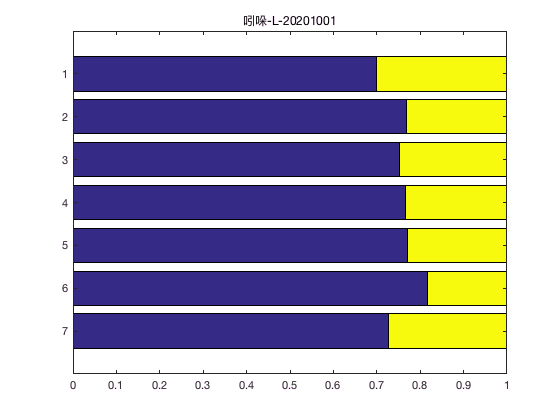

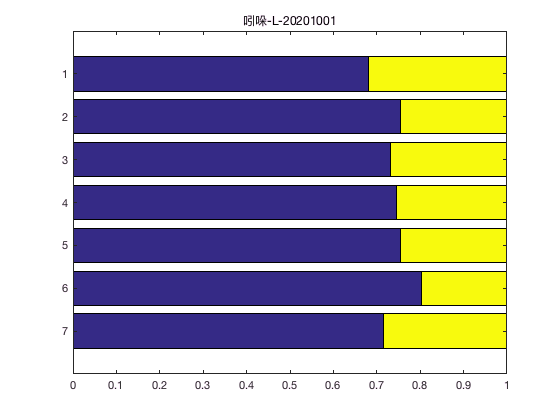

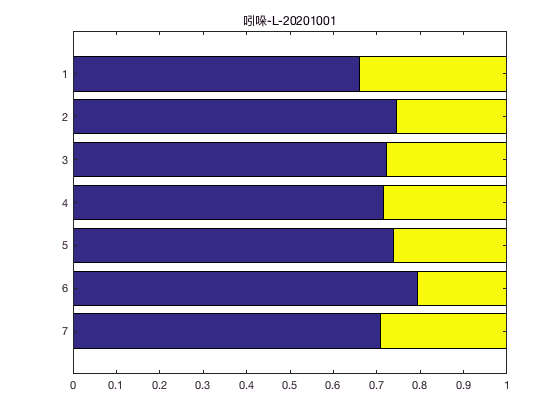

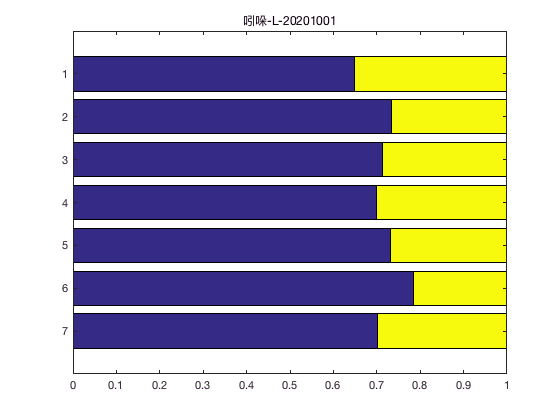

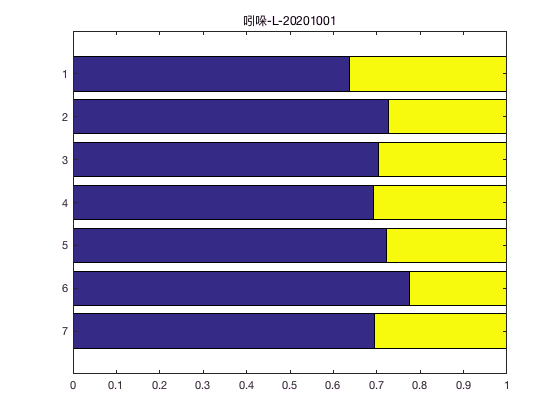

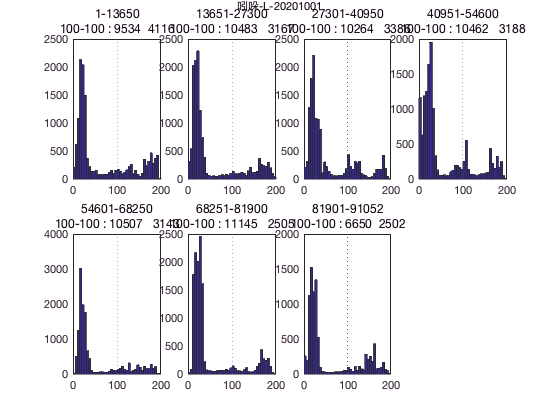

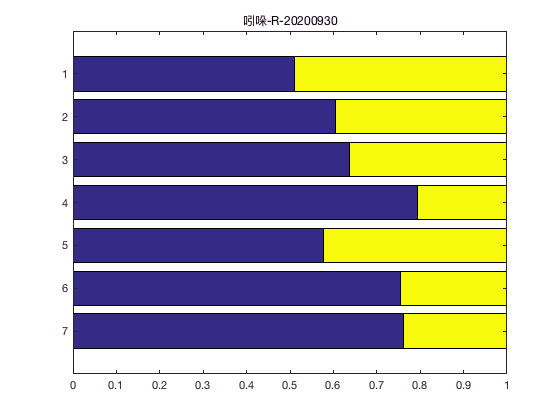

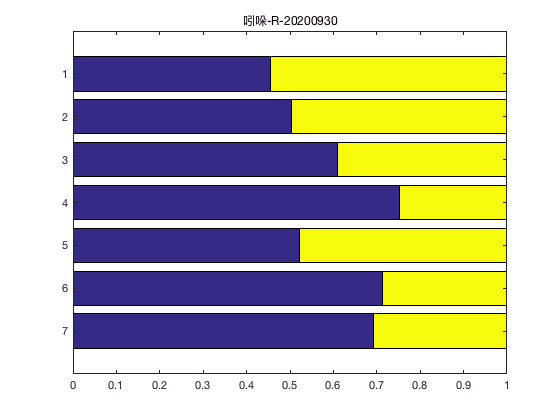

timeint=9.1;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);
    
    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})  
    end
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end